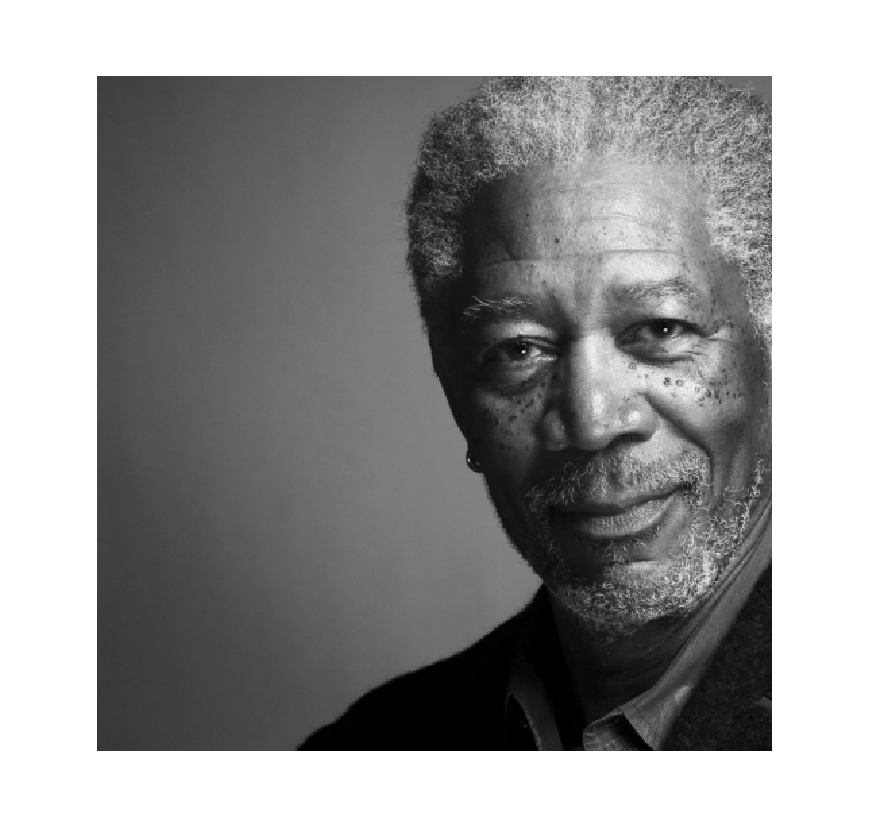

addpath 'C:\Users\baske\OneDrive\Desktop\ECE_4510_Machine_Vision\Project1_20231007'
MorgFree = imread('Morgan.tif');
figure;
imshow(MorgFree);
truesize([300 300]);


%Average filter
H1 = fspecial('average', 7);
MorganFree_AvgFilter = imfilter(MorgFree,H1);

%Disk filter
H2 = fspecial('disk',3);
MorganFree_DiskFilter = imfilter(MorgFree,H2);

%Guassion filter
H3 = fspecial('gaussian',7, 0.5);
MorganFree_GuassianFilter = imfilter(MorgFree,H3);


## **Task 2 Part A:**

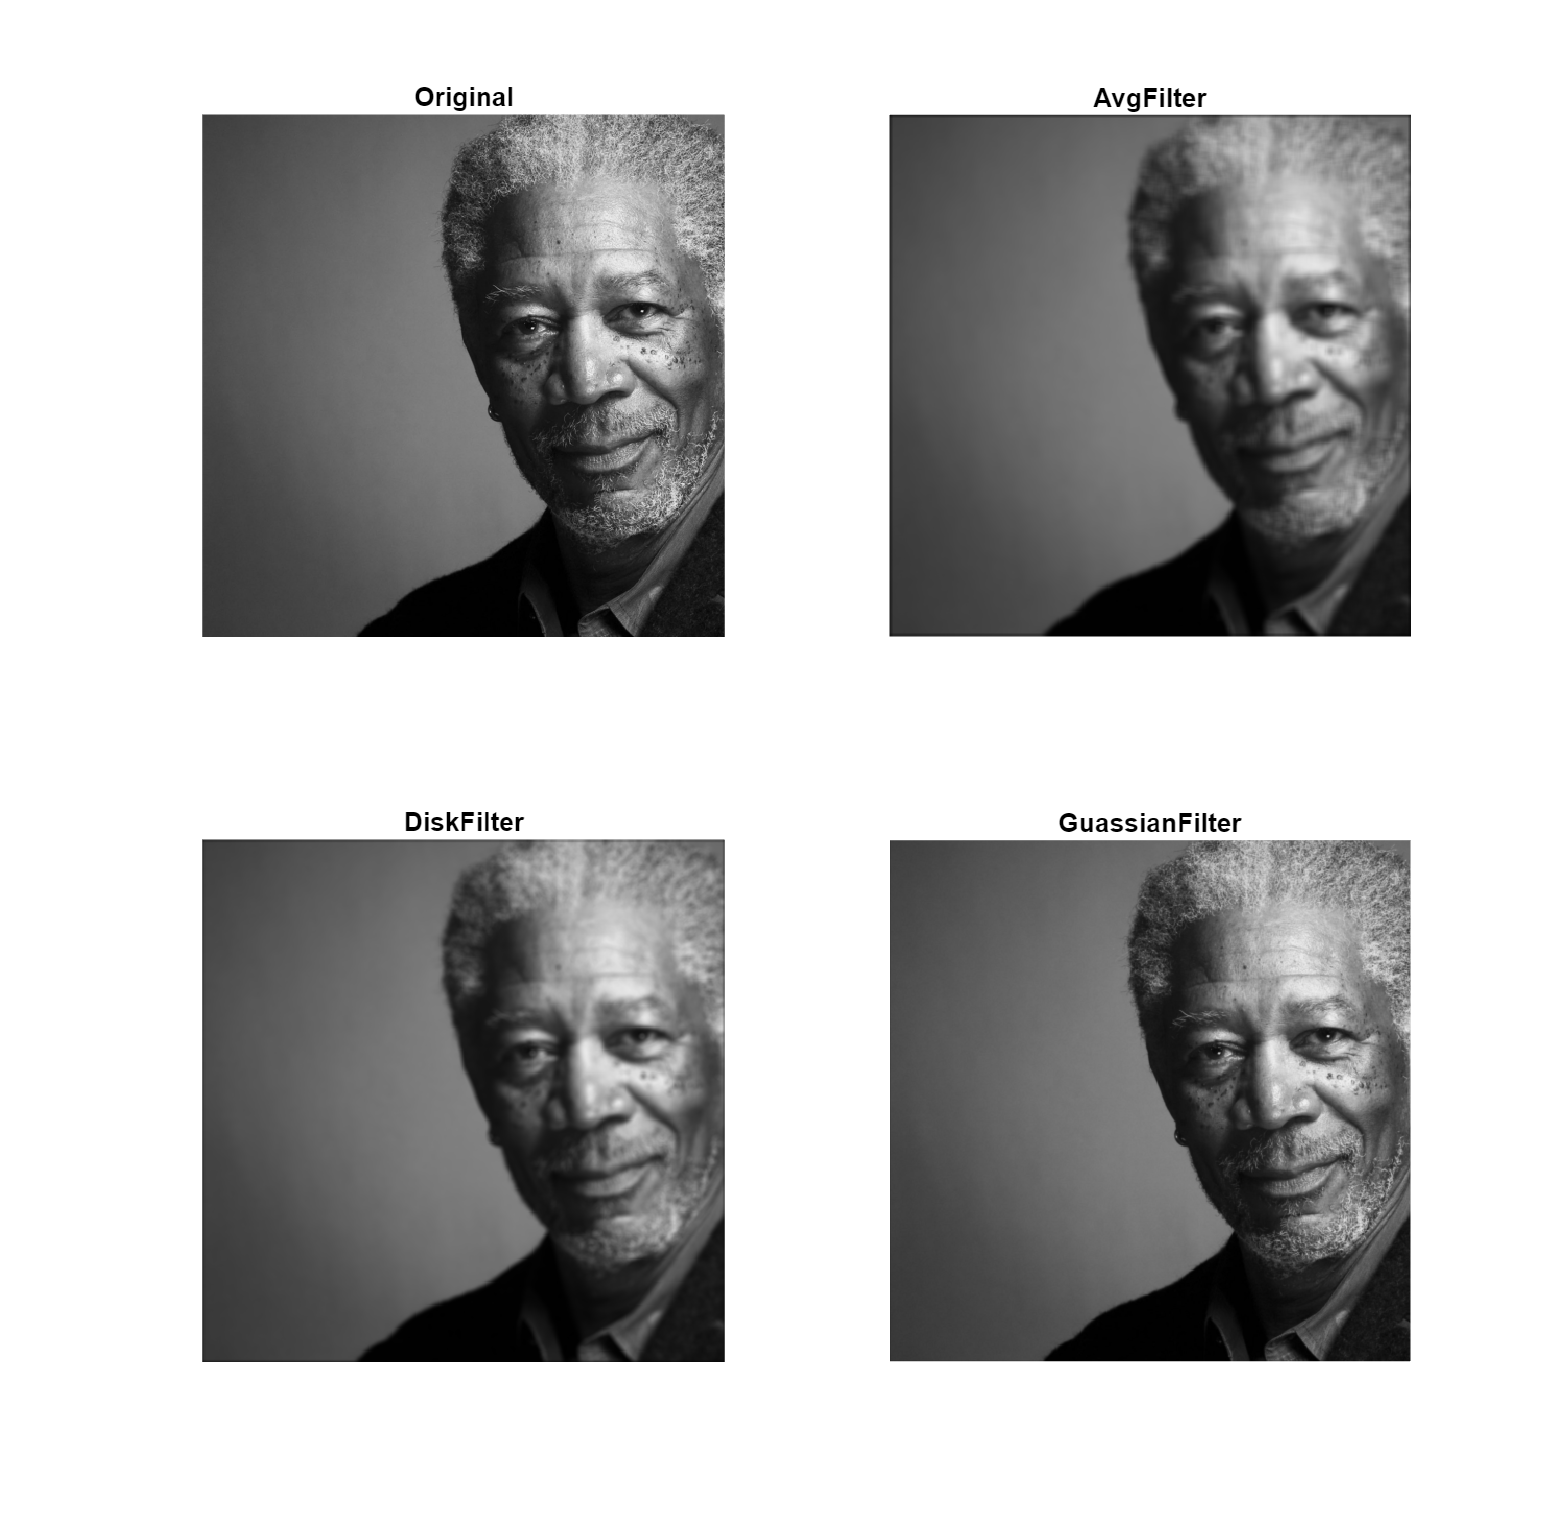

figure

subplot(2,2,1)
imshow(MorgFree)
title('Original');

subplot(2,2,2)
imshow(MorganFree_AvgFilter)
title('AvgFilter');


subplot(2,2,3)
imshow(MorganFree_DiskFilter)
title('DiskFilter');


subplot(2,2,4)

imshow(MorganFree_GuassianFilter)
title('GuassianFilter');

truesize([300 300]);

## **Task  2 Part B**

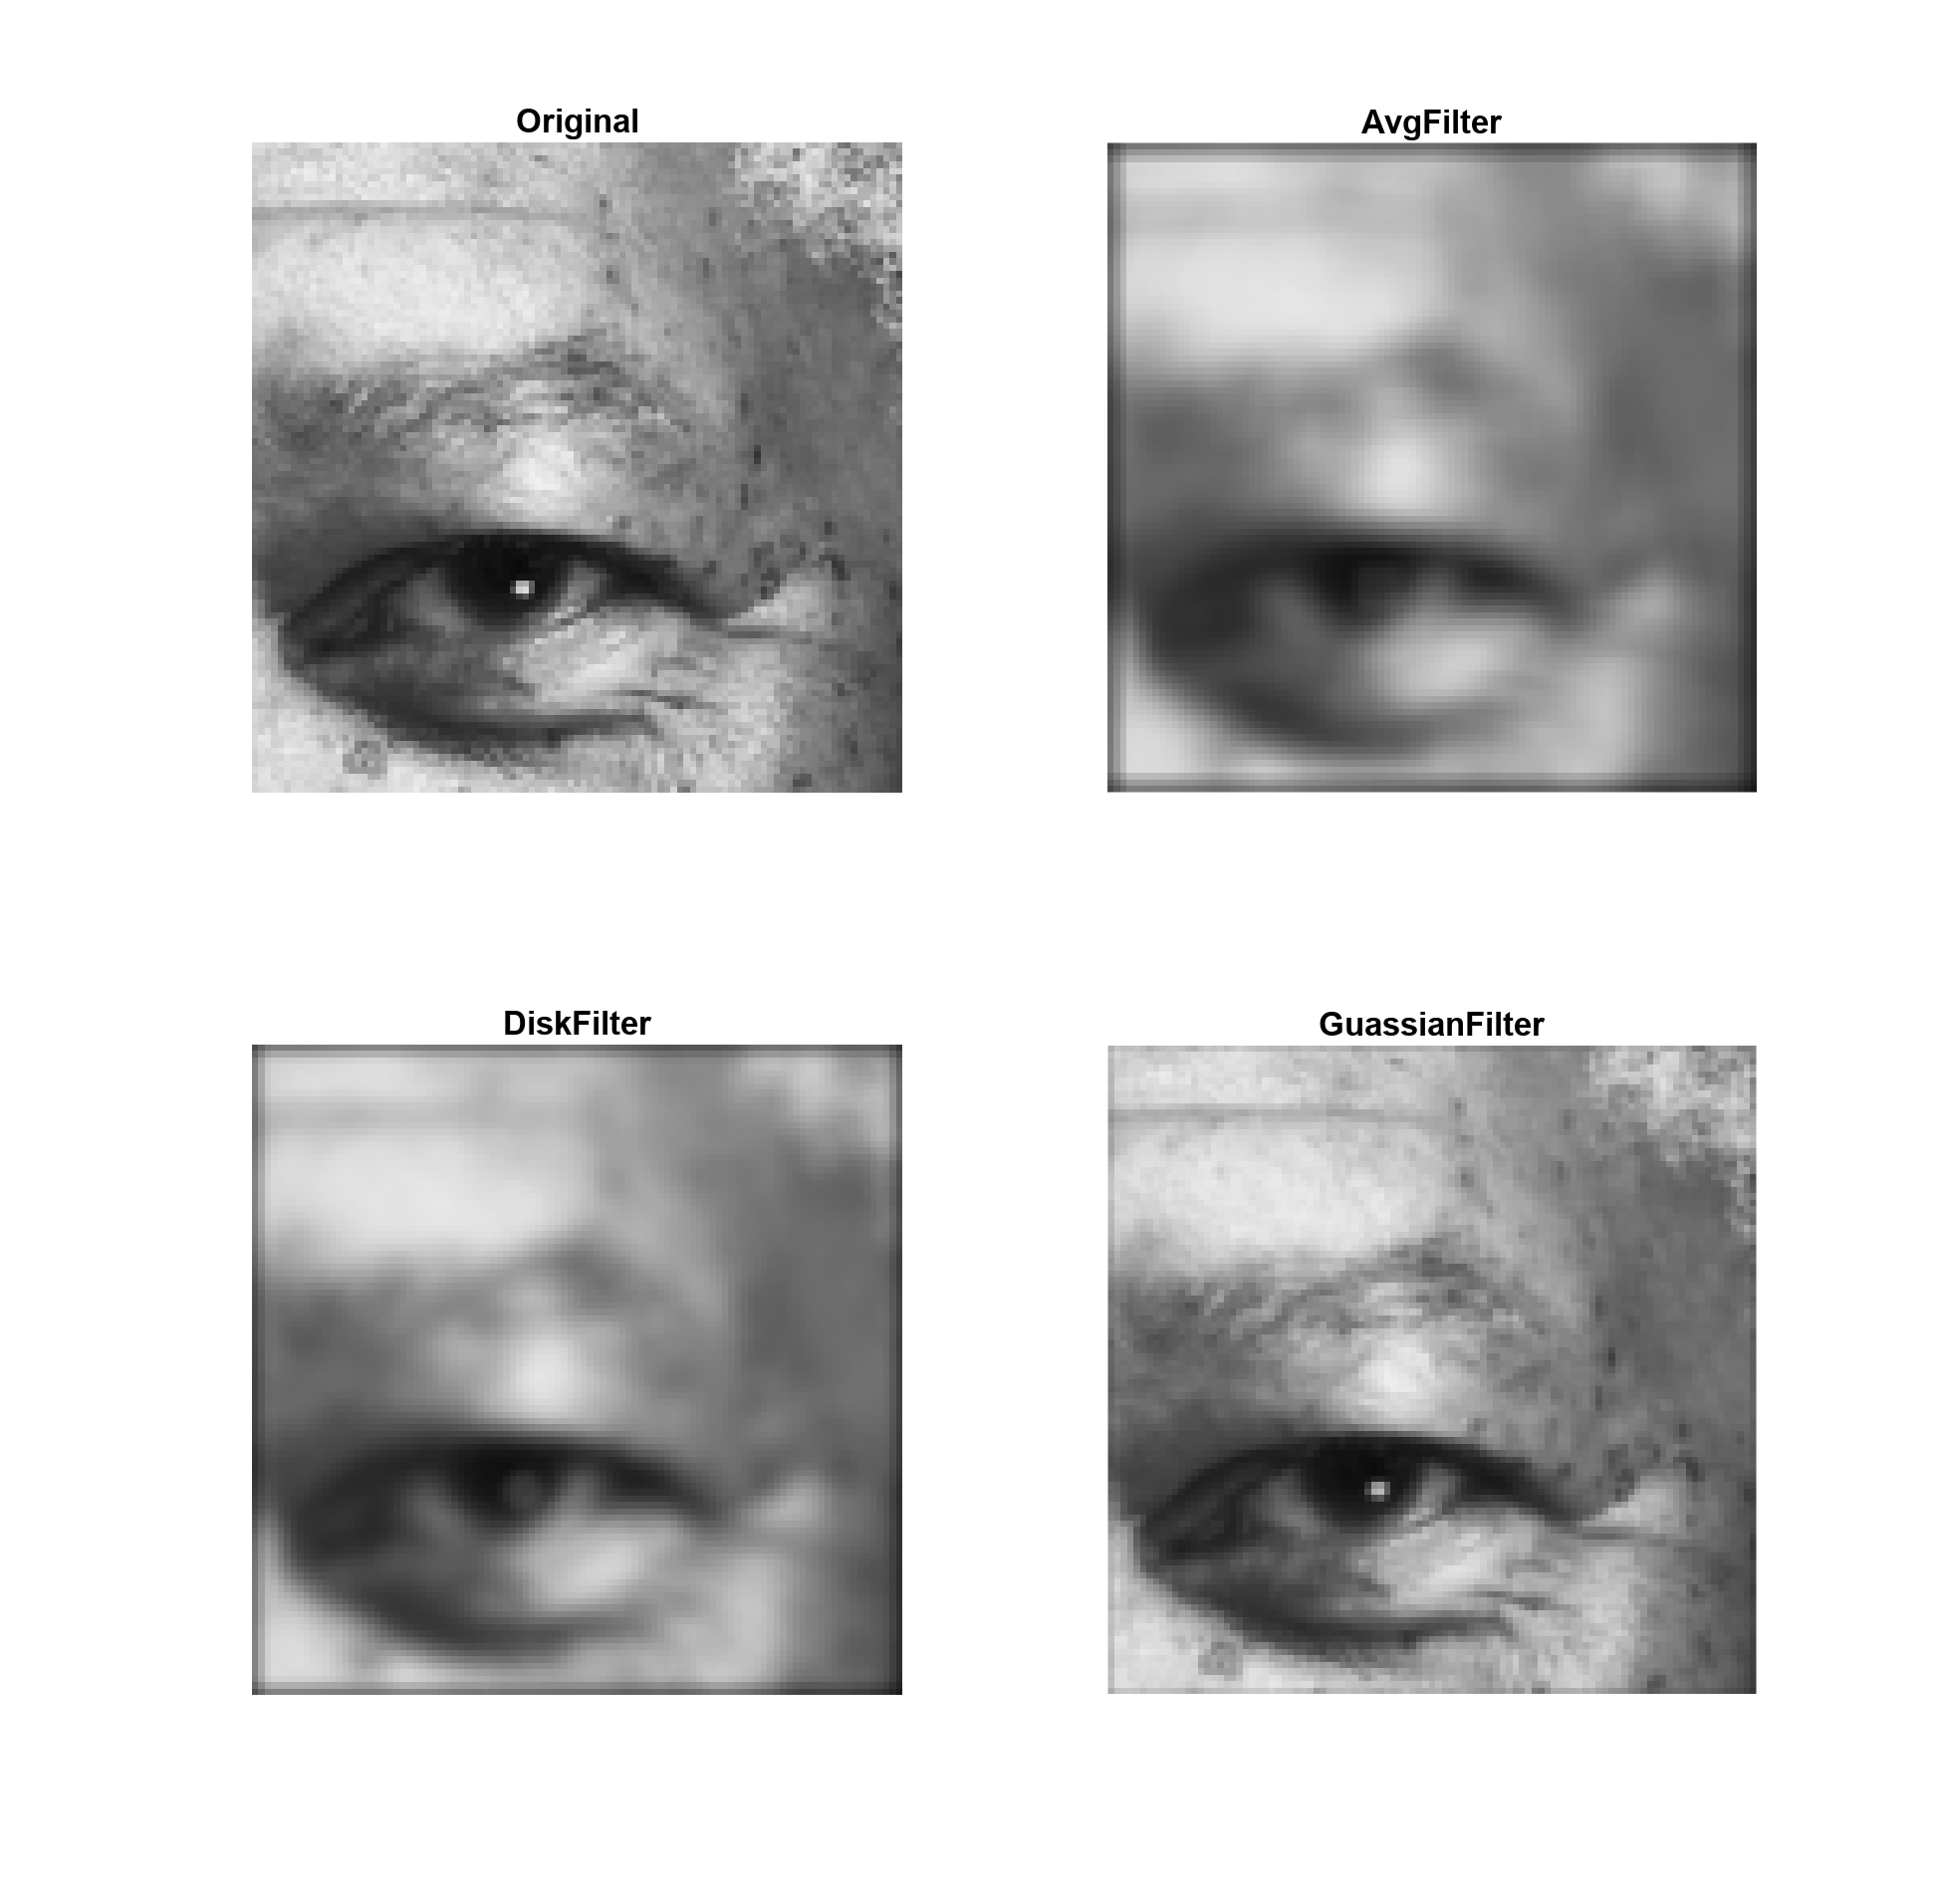

%Now, subtracting original


OrigSubAvgFilter = imsubtract(MorgFree, MorganFree_AvgFilter);

OrigSubDiskFilter = imsubtract(MorgFree, MorganFree_DiskFilter);

OrigSubGuassianFilter = imsubtract(MorgFree, MorganFree_GuassianFilter);

%Adding Filters

TwoOrigSubAvgFilter = 2* OrigSubAvgFilter;
Orig_Add_OrigSubAvgFilter = imadd(MorgFree, TwoOrigSubAvgFilter);
TwoOrigSubAvgFilter = 2*OrigSubDiskFilter;
Orig_Add_OrigSubDiskFilter = imadd(MorgFree, TwoOrigSubAvgFilter);
TwoOrigSubGuassianFilter = 2*OrigSubGuassianFilter;
Orig_Add_OrigSubGuassianFilter = imadd(MorgFree, TwoOrigSubGuassianFilter);


MorgFree = imread('Morgan.tif');


EyeballFreeman = imcrop(MorgFree,[380 120 100 100]); %[Xmin Ymin width height]

%Average Filter
HEye1 = fspecial('average', 7);
EyeMorganFree_AvgFilter = imfilter(EyeballFreeman,HEye1);

%Disk Filter
HEye2 = fspecial('disk',3);
EyeMorganFree_DiskFilter = imfilter(EyeballFreeman,HEye2);

%Guassion Filter
HEye3 = fspecial('gaussian',7, 0.5);
EyeMorganFree_GuassianFilter = imfilter(EyeballFreeman,HEye3);

figure

subplot(2,2,1)

imshow(EyeballFreeman)
title('Original');

subplot(2,2,2)
imshow(EyeMorganFree_AvgFilter)
title('AvgFilter');


subplot(2,2,3)
imshow(EyeMorganFree_DiskFilter)
title('DiskFilter');


subplot(2,2,4)

imshow(EyeMorganFree_GuassianFilter)
title('GuassianFilter');

truesize([300 300]);

**In the images showed above, it is clear that the average filter is the most blurred, disk is still blurry and the guassian filter is the least blurry out of the filters. Also, you can see lines within the average and disk filters as well.**

## **Task 2 Part C**

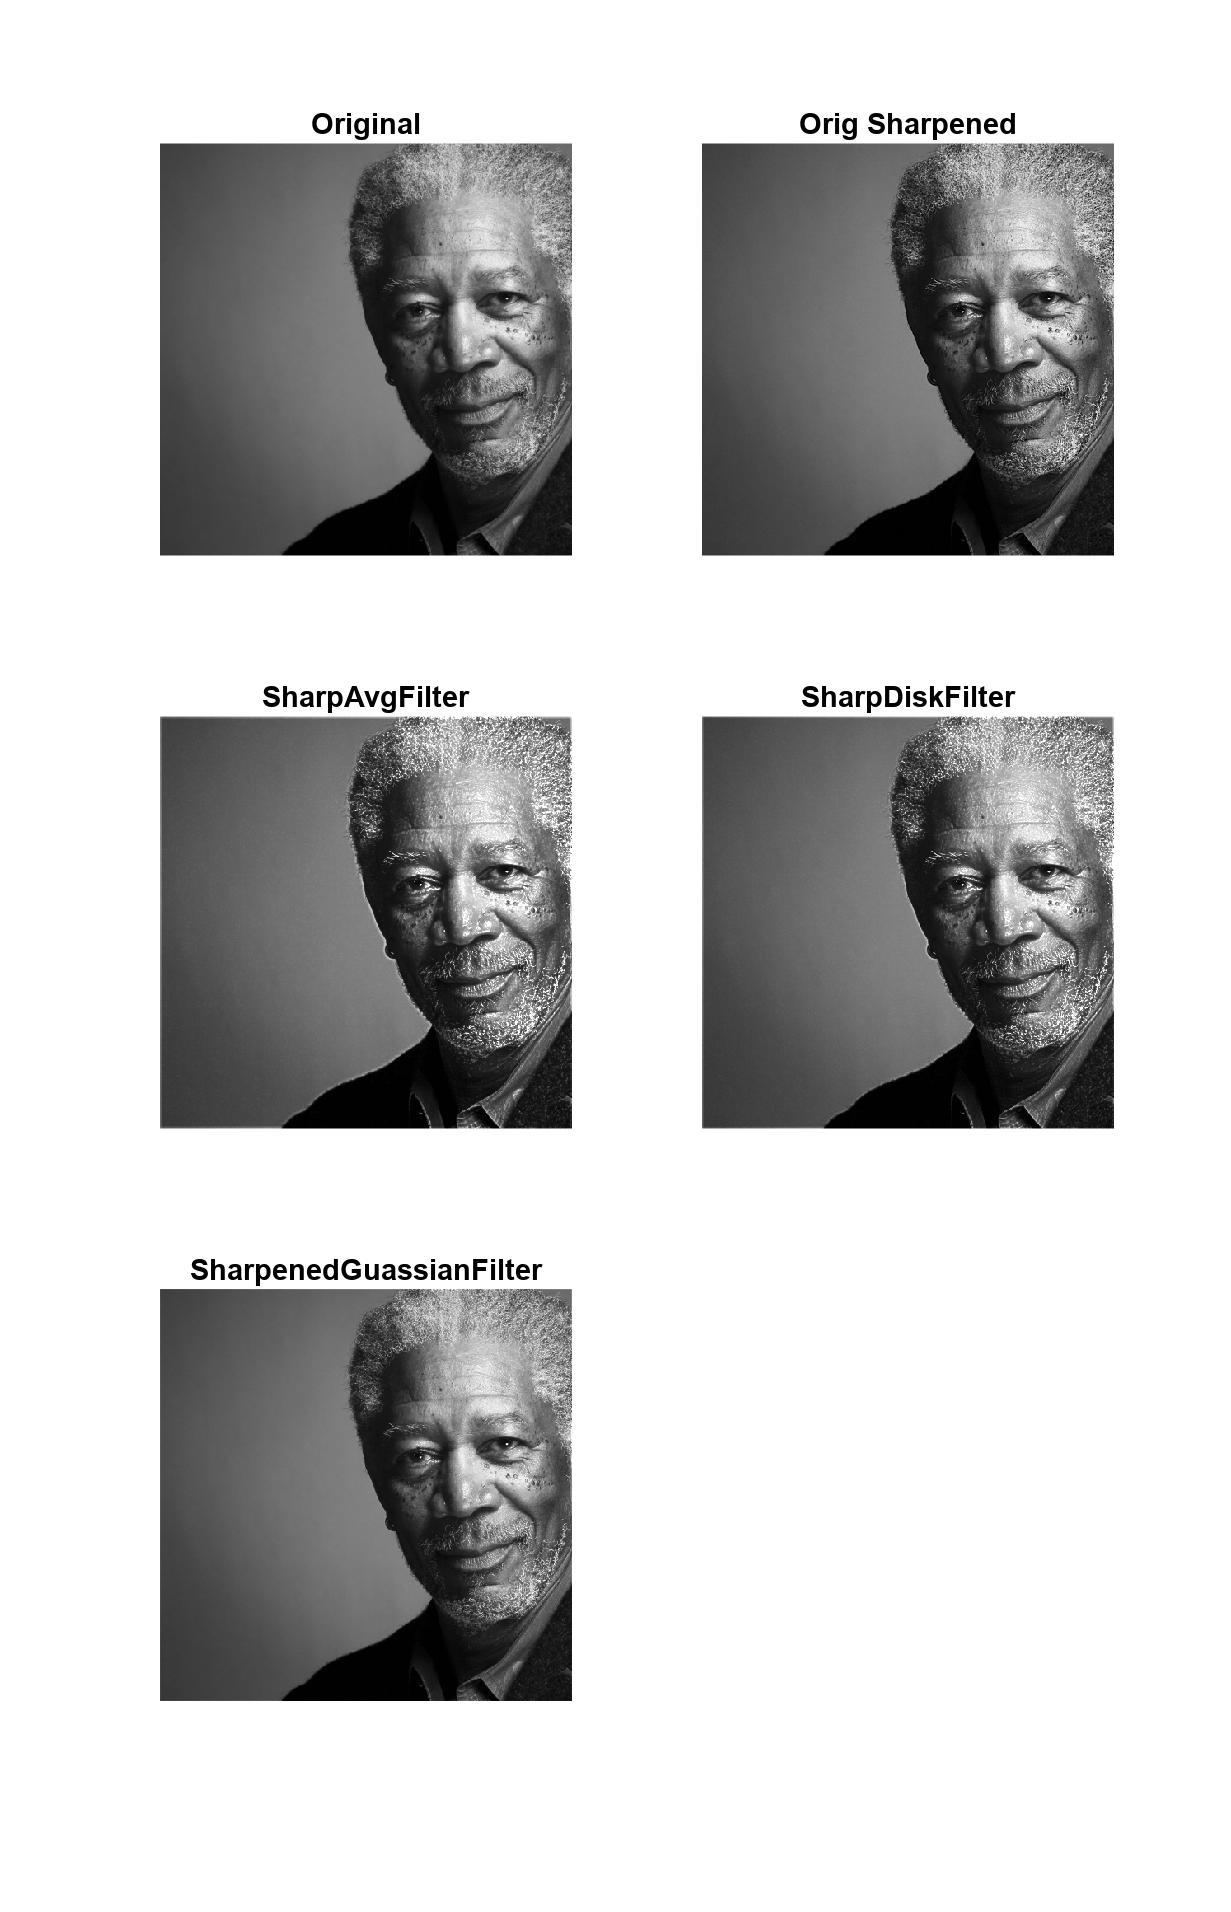


figure

subplot(3,2,1)
imshow(MorgFree)
title('Original');

subplot(3,2,2)
SharpMorgFree = imsharpen(MorgFree);
imshow(SharpMorgFree)
title('Orig Sharpened');

subplot(3,2,3)
imshow(Orig_Add_OrigSubAvgFilter)
title('SharpAvgFilter');


subplot(3,2,4)
imshow(Orig_Add_OrigSubDiskFilter)
title('SharpDiskFilter');


subplot(3,2,5)
imshow(Orig_Add_OrigSubGuassianFilter)
title('SharpenedGuassianFilter');

truesize([200 200]);

## **Task 2, Part D:**

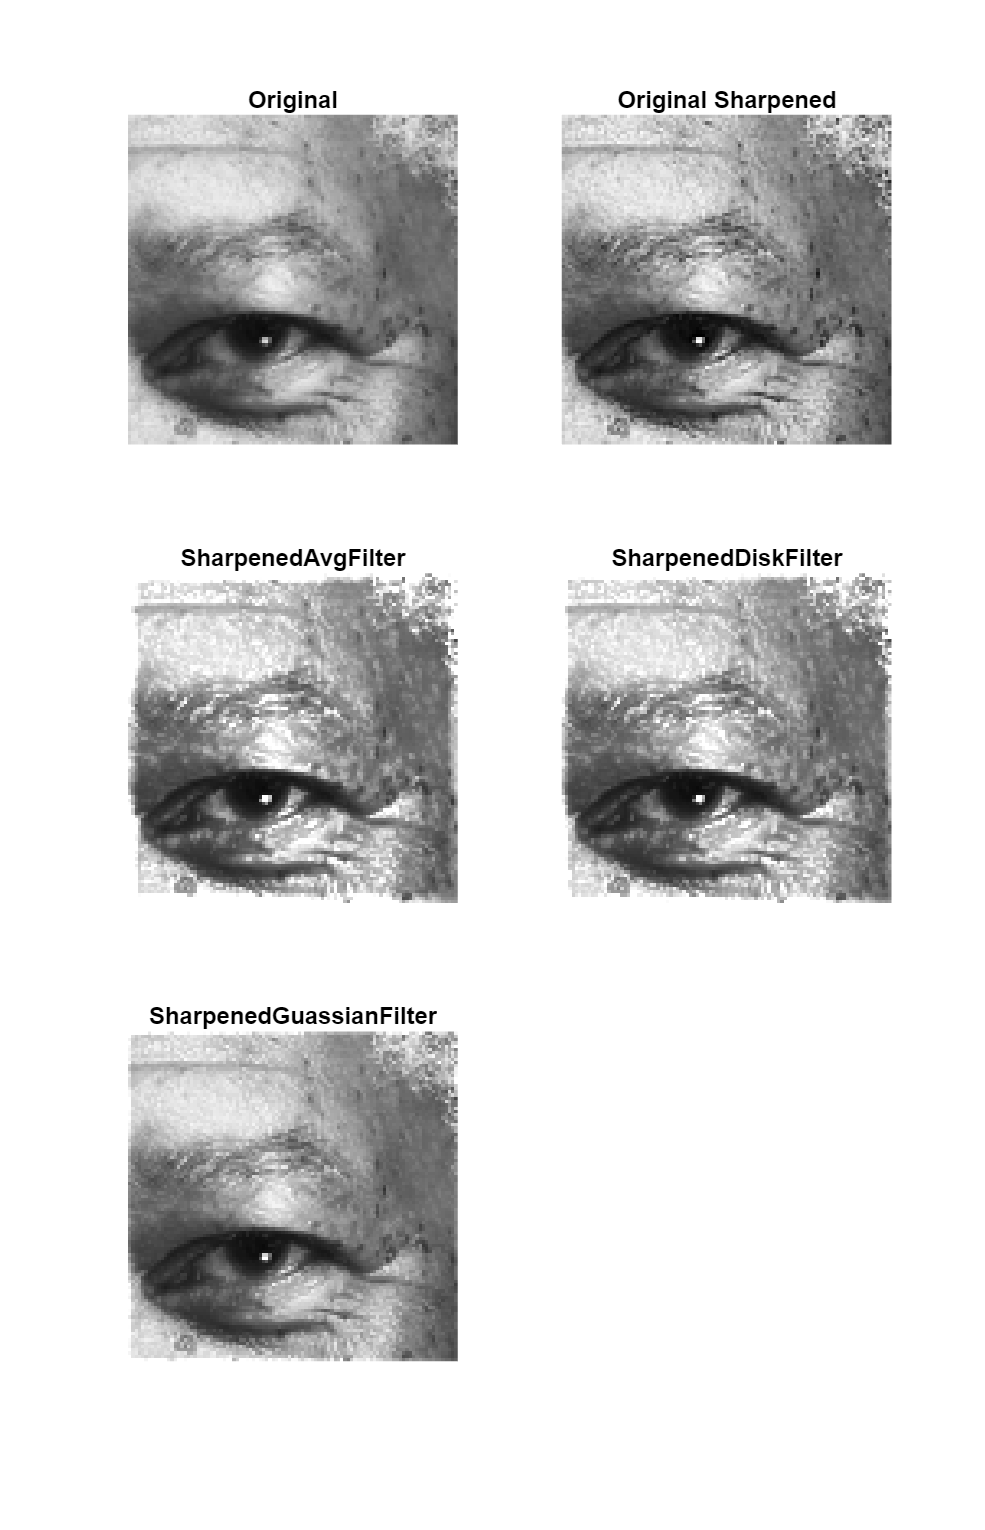


EyeOrigSubAvgFilter = imsubtract(EyeballFreeman, EyeMorganFree_AvgFilter);

EyeOrigSubDiskFilter = imsubtract(EyeballFreeman, EyeMorganFree_DiskFilter);

EyeOrigSubGuassianFilter = imsubtract(EyeballFreeman, EyeMorganFree_GuassianFilter);





EyeTwoOrigSubAvgFilter = 2*EyeOrigSubAvgFilter;
EyeOrig_Add_OrigSubAvgFilter = imadd(EyeballFreeman, EyeTwoOrigSubAvgFilter);
EyeTwoOrigSubDiskFilter = 2*EyeOrigSubDiskFilter;
EyeOrig_Add_OrigSubDiskFilter = imadd(EyeballFreeman, EyeTwoOrigSubDiskFilter);
EyeTwoOrigSubGuassianFilter = 2*EyeOrigSubGuassianFilter;
EyeOrig_Add_OrigSubGuassianFilter = imadd(EyeballFreeman, EyeTwoOrigSubGuassianFilter);



figure

subplot(3,2,1)
imshow(EyeballFreeman)
title('Original');

subplot(3,2,2)
SharpEyeballFreeman = imsharpen(EyeballFreeman);
imshow(SharpEyeballFreeman)
title('Original Sharpened');

subplot(3,2,3)
imshow(EyeOrig_Add_OrigSubAvgFilter)
title('SharpenedAvgFilter');


subplot(3,2,4)
imshow(EyeOrig_Add_OrigSubDiskFilter)
title('SharpenedDiskFilter');


subplot(3,2,5)
imshow(EyeOrig_Add_OrigSubGuassianFilter)
title('SharpenedGuassianFilter');

truesize([200 200]);

### **Looking at the sharpened images above, it is clear that the "Original sharpened" and the Sharpened Guassian look very similar to one another. The Average and Disk Filter also have similarities between eachother too, such as the area showing Morgan Freeman's hair.**